# Sprawozdanie Lisek Mańka

## Dane wykorzystane do nauki sieci

## 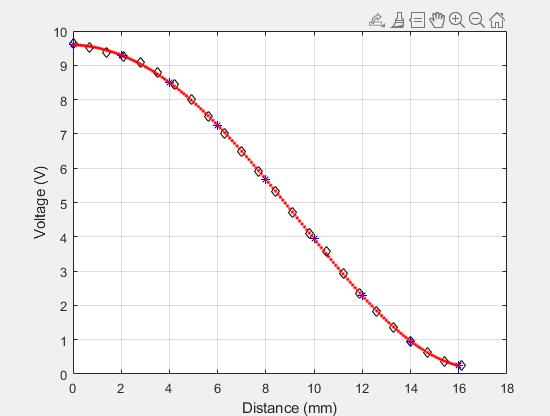

## Test sieci neuronowej dla 9 próbek

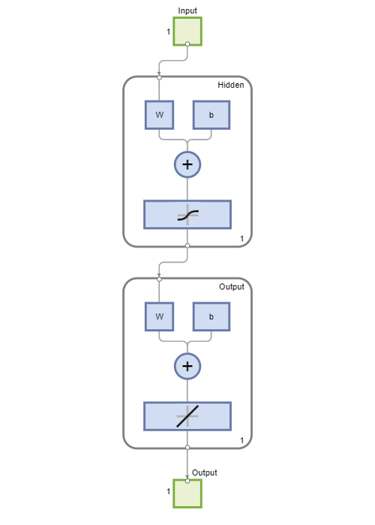

x_train = SensorData9p.Distance_mm';
y_train = SensorData9p.Sensor_V';

net = feedforwardnet(1, 'trainlm');
net = train(net, x_train, y_train);

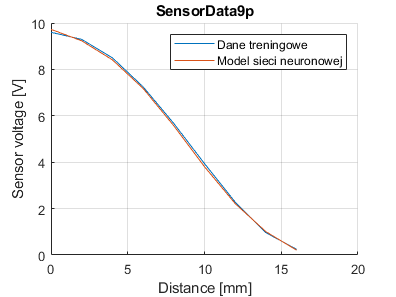

view(net);

y_net = net(x_train);

figure;
hold on
plot(x_train, y_train)
plot(x_train, y_net)
hold off
legend("Dane treningowe", 'Model sieci neuronowej')
xlabel('Distance [mm]')
ylabel('Sensor voltage [V]')
title('SensorData9p')
grid on


perf = perform(net,y_train, y_net)

perf = 0.0076

Została również przetestowana sieć neuronowa dla odwróconych wartości osi x i osi 

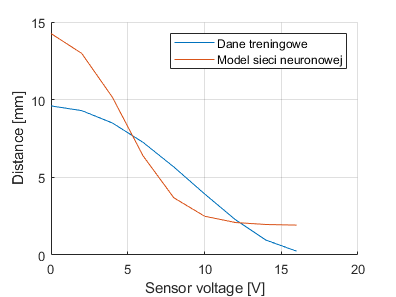

x_train = SensorData9p.Distance_mm';
y_train = SensorData9p.Sensor_V';

net = feedforwardnet(1, 'trainlm');
net = train(net, y_train, x_train);

y_net = net(x_train);

figure;
hold on
plot(x_train, y_train)
plot(x_train, y_net)
hold off
legend("Dane treningowe", 'Model sieci neuronowej')
ylabel('Distance [mm]')
xlabel('Sensor voltage [V]')
grid on


perf = perform(net,y_train, y_net)

perf = 5.4073

Został również sprawdzony wynik dla innej funkcji trenującej

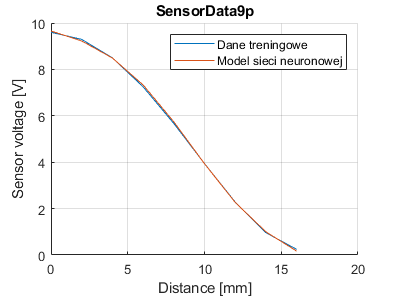

x_train = SensorData9p.Distance_mm';
y_train = SensorData9p.Sensor_V';

net = feedforwardnet(1, 'trainbfg');
net = train(net, x_train, y_train);

y_net = net(x_train);

figure;
hold on
plot(x_train, y_train)
plot(x_train, y_net)
hold off
legend("Dane treningowe", 'Model sieci neuronowej')
xlabel('Distance [mm]')
ylabel('Sensor voltage [V]')
title('SensorData9p')
grid on


perf = perform(net,y_train, y_net)

perf = 0.0030

## Test sieci neuronowej dla 24 próbek

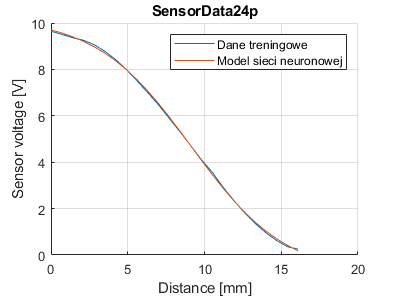

x_train = SensorData24p.Distance_mm';
y_train = SensorData24p.Sensor_V';

net = feedforwardnet(1, 'trainlm');
net = train(net, x_train, y_train);

y_net = net(x_train);

figure;
hold on
plot(x_train, y_train)
plot(x_train, y_net)
hold off
legend("Dane treningowe", 'Model sieci neuronowej')
xlabel('Distance [mm]')
ylabel('Sensor voltage [V]')
title('SensorData24p')
grid on


perf = perform(net,y_train, y_net)

perf = 0.0033

## Test sieci neuronowej dla 161 próbek

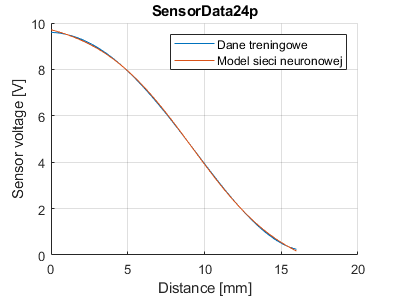

x_train = SensorData161p.Distance_mm';
y_train = SensorData161p.Sensor_V';

net = feedforwardnet(1, 'trainlm');
net = train(net, x_train, y_train);

y_net = net(x_train);

figure;
hold on
plot(x_train, y_train)
plot(x_train, y_net)
hold off
legend("Dane treningowe", 'Model sieci neuronowej')
xlabel('Distance [mm]')
ylabel('Sensor voltage [V]')
title('SensorData24p')
grid on


perf = perform(net,y_train, y_net)

perf = 0.0013

## Wnioski

Podczas ćwiczeń sieć neuronowa została testowana dla różnych danych. Im więcej danych tym mniejszy błąd średniokwadratowych, który był odczytywany przy pomocy funkcji perform.

Dużą rolę w trenowaniu sieci neuronowych odgrywa poprawny dobór danych. Dla zmienionych wartości x i y sieć nie była wstanie dopasować. Dane napięcia są od siebie oddalone nierównomierne. Dane dystansu były oddalone co 2mm. 

x_train = SensorData9p.Distance_mm'

x_train =      0     2     4     6     8    10    12    14    16


y_train = SensorData9p.Sensor_V'

y_train =     9.5986    9.2948    8.4981    7.2501    5.6701    3.9385    2.2826    0.9604    0.2457


W funkcji feedforwardnet domyślna funkcja ucząca to Levenberg-Marquardt. Dla 9 próbek znacznie lepszy wynik uzyskaliśmy z funkcji BFGS Quasi Newtona. 